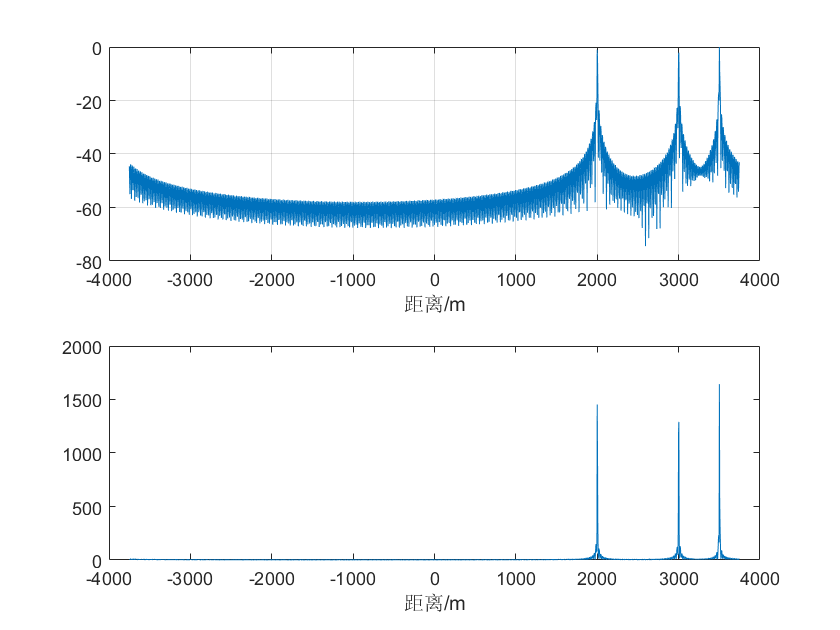

%%%%%%%%%%%%%%%%%%%%%%%%  去斜处理仿真程序  %%%%%%%%%%%%%%%%%%%%%%%%%
clc;clear all;close all;
B=10e6;%带宽10MHz
tp=10e-6;%脉宽10us
k=B/tp;%LFM系数
fs=50e6;
R0=3e3;R1=2000;R2=3500;R=5000;
c=3e8;
f0=60e6;
 
N=round(2*R/c*fs);
fft_N=2^nextpow2(N);
t=linspace(0,2*R/c,N);
 
 
%%%%%%%%%%%%%%%%%%%%%%%%%%   参考信号   %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
Sref=exp(2i*pi*f0*t).*exp(1i*pi*k*t.^2);
%%%%%%%%%%%%%%%%%%%%%%%%%%%   回波信号   %%%%%%%%%%%%%%%%%%%%%%%%%%%%
Sb0=exp(1j*pi*k*(t-2*R0/c).^2).*exp(2j*pi*f0*(t-2*R0/c));
Sb1=exp(1j*pi*k*(t-2*R1/c).^2).*exp(2j*pi*f0*(t-2*R1/c));
Sb2=exp(1j*pi*k*(t-2*R2/c).^2).*exp(2j*pi*f0*(t-2*R2/c));
Sb=Sb0+Sb1+Sb2;
%%%%%%%%%%%%%%%%%%%%%%%%%%%   混频信号   %%%%%%%%%%%%%%%%%%%%%%%%%%%%
SSb=Sref.*conj(Sb);%去斜后时域信号
spectrum=fft(SSb,fft_N);%去斜后频域信号
f=fs*(0:fft_N-1)/fft_N-fs/2;%从-fs/2到fs/2
f=f*c*tp/2/B;%瞬时频率对应的距离
sf=exp(-j*pi/k*f.^2);%滤波器传输函数
SSb=spectrum.*sf;%从频域去距离扭曲，实现了压缩和去RVP
figure;
SSb=fftshift(SSb);
SSb1=ifft(SSb);%消除了距离扭曲和RVP的时域信号
subplot(211);
plot(f,db(abs(SSb)/max(SSb)))
xlabel('距离/m');
grid on
subplot(212);
plot(f,abs(SSb))
xlabel('距离/m');